Incremental Anomaly Detection 

Create a set of normal data with a small mix of anomaly.

load features.mat
feaTrain = feaTrain([1:5,300:350],:);
rng(0,"twister"); % To reproduce across sessions
feaTrain = feaTrain(randperm(height(feaTrain)),:);

Traditional SVM

% Mdl = fitcsvm()

Create a incremental one-class SVM model 

Mdl = incrementalOneClassSVM("ContaminationFraction",0.1,"ScoreWindowSize",5);
Mdl.ScoreWarmupPeriod

ans = 0

Mdl.ContaminationFraction

ans = 0.1000

Incremental fitting with a few normal observation

% Incremental fitting
rng(0,"twister"); % To reproduce across sessions
n=height(feaTrain);
medianscore = zeros(n,1);
threshold = zeros(n,1);    
numAnom = zeros(n,1);
allscores = [];
for j = 1:n
    Mdl = fit(Mdl,feaTrain{j,2:end});
    [isanom,scores] = isanomaly(Mdl,feaTrain{j,2:end});
    medianscore(j) = median(scores);
    allscores = [allscores scores'];    %#ok<AGROW>
    numAnom(j) = sum(isanom);
    threshold(j) = Mdl.ScoreThreshold;
end

Plot the anomaly score for every observation. 

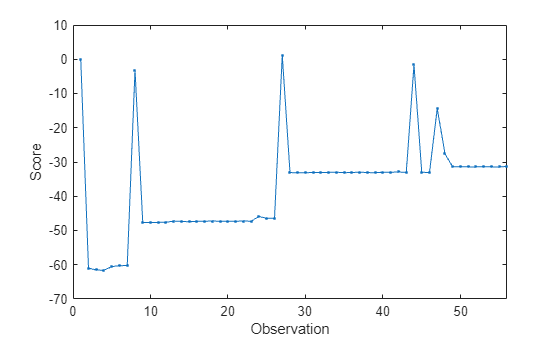

figure
plot(allscores,".-")
xlabel("Observation")
ylabel("Score")
xlim([0 n])

Check  how the score threshold and median score per data chunk evolve during training, plot them on separate tiles.

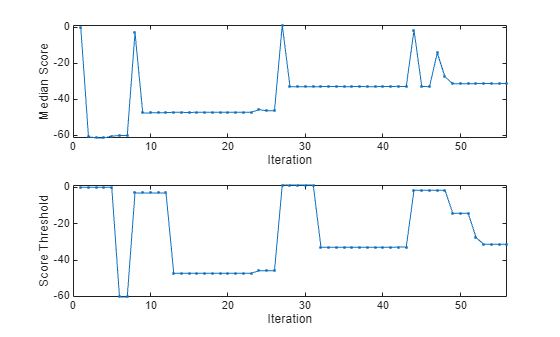

figure
tiledlayout(2,1);
nexttile
plot(medianscore,".-")
ylabel("Median Score")
xlabel("Iteration")
xlim([0 n])
nexttile
plot(threshold,".-")
ylabel("Score Threshold")
xlabel("Iteration")
xlim([0 n])

finalScoreThreshold=Mdl.ScoreThreshold

finalScoreThreshold = -31.3012

Test anomaly detector

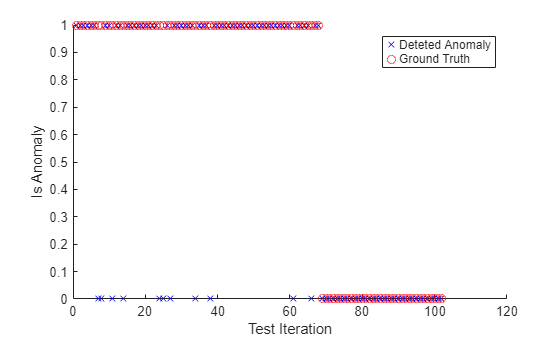

[isanomTest,scoresTest] = isanomaly(Mdl,feaTest{:,2:end});
figure;hold on
plot(1:height(feaTest),isanomTest,'bx');
plot(1:height(feaTest),feaTest{:,1}~="Normal",'ro');
legend("Deteted Anomaly","Ground Truth")
ylabel("Is Anomaly")
xlabel("Test Iteration")